#### **Motivation :**

The Argo floats program has taken wide acceptance in recent years. Instead of data profiling through instruments carried on ships, Argo independently collects temperature and salinity profiles throughout most of the open ocean. 

The range of Argo measurements is upto 2000m. Recent Argo analysis has recognized that there exists higher temperature and salinity variability in specific regions and has called for doubled Argo density such as in the tropics (Roemmich et al. 2019).

#### **Introduction:**

The tropics profoundly impacts global weather and sea temperature pattern. Higher than average variability in sea surface temperature of the region between -5°N to 5°N and 190 to 240 °E is measured in terms of El Nino Index. Argo floats with their continuous data can help oceanographers understand the correlation between temperature & Salinity and El-Nino.

In this study, we use Argo data to calulate covariance matrices of Salinity and Temperature over spatial map. We calculate percentage weight of various modes affecting the variation in time and decipher what modes represent physically. We finally determine if Mode reprsented by El-Nino has strong correlation with ONI index.

Other plots which help in analysis include variation across and along NINO 3.4 Index box, stacked plot of diagonal matrices and Individual mode plots for both temperature and salinity.

The data is taken from Scripps managed  [https://sio-argo.ucsd.edu/RG_Climatology.html](https://sio-argo.ucsd.edu/RG_Climatology.html) which also contributes to National Argo Program.

clear all

file = 'RG_ArgoClim_Temperature_2019.nc';
ncid = netcdf.open(file);
A_number = netcdf.getVar(ncid,3);

meta = ncinfo('RG_ArgoClim_Temperature_2019.nc');
disp('Variable List');

Variable List


disp({meta.Variables.Name}');

    {'LONGITUDE'               }
    {'LATITUDE'                }
    {'PRESSURE'                }
    {'TIME'                    }
    {'ARGO_TEMPERATURE_MEAN'   }
    {'ARGO_TEMPERATURE_ANOMALY'}
    {'BATHYMETRY_MASK'         }
    {'MAPPING_MASK'            }



temperature_a = ncread(file,'ARGO_TEMPERATURE_ANOMALY');
size(temperature_a)

ans =    360   145    58   180


lon = ncread(file,'LONGITUDE');
lat = ncread(file,'LATITUDE');
t =  ncread(file,'TIME');
tmon = datenum(2004,1+(0:length(t)-1)',15);
pressure = ncread(file,'PRESSURE');

### **Method :**

1) Average the temperature anomaly of Pacific Ocean surface ( < 100 m)

2) Find index values of the region of concern: -5°N to 5°N, 152.5°E to 298.5°E

3) Plot the spatial variation of temperature.

k = find(pressure < 100);
pressure(k);
temperature_100_a = mean(temperature_a(:,:,k),3);

size(temperature_a);
%Longitude-360,Latitude-145,Pressure-58,Time (Months)-180
size(temperature_100_a);
%Longitude-360,Latitude-145

temperature_a(111,65,:,:);
temperature_a(261,65,:,:);

lon(133);   %152.5
lon(279);   %298.5

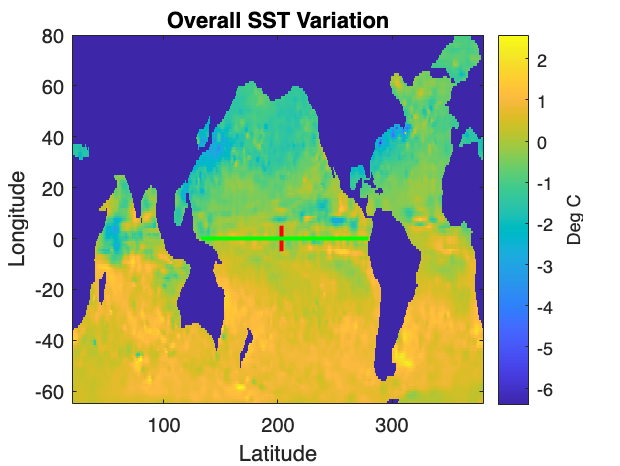

imagesc(lon,lat,squeeze(temperature_100_a(:,:,end))')
set(gca,'ydir','normal')
%Area of Concern: Latitude  -5N to 5N, Longitude 152.5 to  298.5
line([203,203],[-5,5],'Color','r','LineWidth',2)
line([133,279],[0,0],'Color','g','LineWidth',2)
xlabel('Latitude')
ylabel('Longitude')
title('Overall SST Variation')
cb = colorbar;
ylabel(cb,'Deg C')

To see the continuous temperature anomaly variation along and across NINO 3.4 region,

4) Find end points of Nino 3.4 Index,

5) Plot mean temperature anomaly for 2004-2018 for a specific Latitude and Longitude

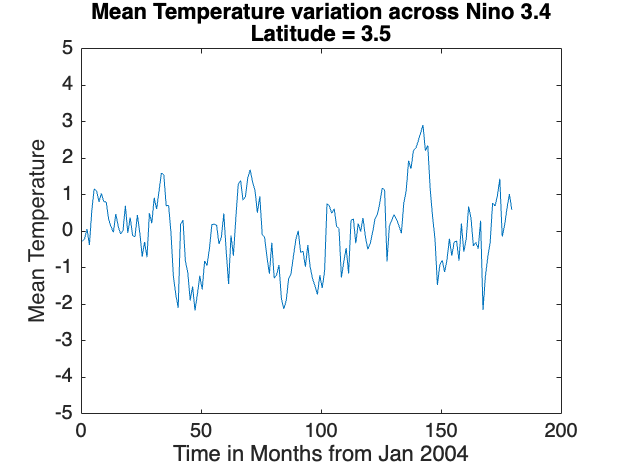

for j = 1:10
    temp_Nino = mean(temperature_a(203,71-j,k,:),3);
    plot(t,squeeze(temp_Nino))
    title({'Mean Temperature variation across Nino 3.4',['Latitude = ',num2str(5.5-j)]})
    xlabel('Time in Months from Jan 2004');
    ylabel('Mean Temperature');
    ylim([-5 5])
    pause (1.5)
end

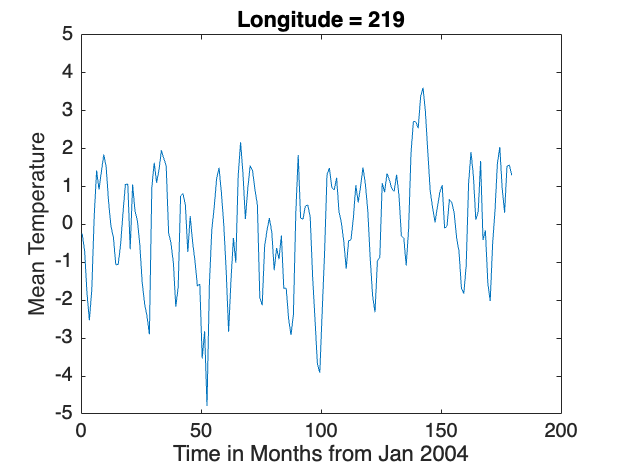

for j = 1:30
    temp_Nino = mean(temperature_a(223-j,71,k,:),3);
    plot(t,squeeze(temp_Nino))
    title({'Mean Temperature variation along Nino 3.4',['Longitude = ',num2str(242.5-j)]})
    title(['Longitude = ',num2str(223-j)])
    xlabel('Time in Months from Jan 2004');
    ylabel('Mean Temperature');
    ylim([-5 5])
    pause (0.7)
end

6) Calculate the pressure averaged temperature anomaly , say pavg

7) Average the pavg over time

8) Calculate Diagonal Matrix whose elements are the singular values from above

9) (Not used for presentation) Plot Diagonal matrix's stacked version

10) Calulate covariance matrix using tranpose Matrix multiplication on D i.e C = D' * D

pavg_temp_Nino = squeeze(mean(temperature_a(:,:,k,:),3));
temp_grid_Nino = squeeze(mean(pavg_temp_Nino,3));
k_ocean = find(~isnan(temp_grid_Nino));
nk = length(k_ocean);
D = NaN(nk,length(t));

T_Lon_P_t = squeeze(temperature_a(112:260,65,:,:));
[mlon,mp,mt] = size(T_Lon_P_t);
D = NaN(mlon*mp,mt);
for j = 1:mt
    TT = squeeze(T_Lon_P_t(:,:,j));
    D(:,j) = TT(:);
end

pcolor(D)
shading interp
title('Depth Profile of Temperature D Matrix')
ylabel('Depth in m')
xlabel('Time')
cb = colorbar

cb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-6.7060 10.3420]
    FontSize: 9
    Position: [0.8496 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


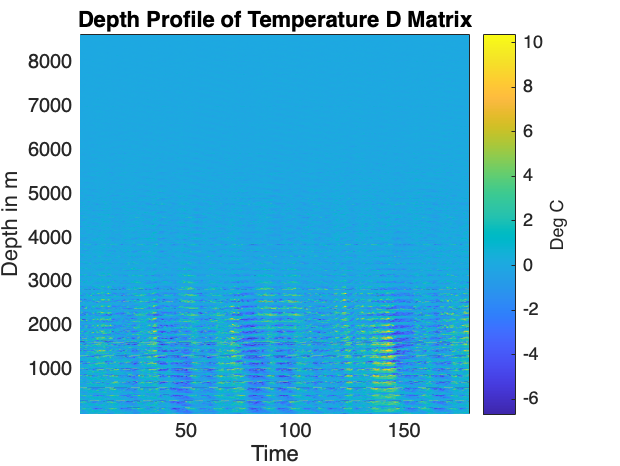

ylabel(cb,'Deg C')

Stacked Version of Temperature anomaly

C = D'*D;
figure (1)
pcolor(t,t,C)
shading interp
cb = colorbar

cb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-1.7314e+04 3.3858e+04]
    FontSize: 9
    Position: [0.8482 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


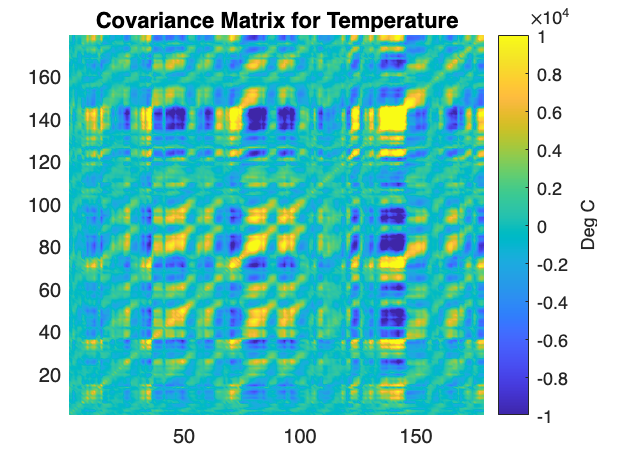

ylabel(cb,'Deg C')
title('Covariance Matrix for Temperature')
caxis([-1e4 1e4])

10) Calculate the eigenvalues lambda and eigen vectors of covariance matrix

11) Reshape matrix to size of longitude by depth sizes

12) Lambda values of each mode determine the strength of each mode

13) Take the values in Column 1 and reshape them to plot against spatial map. This reprsents Mode 1

14) Similarly for Mode 2 and Mode 3

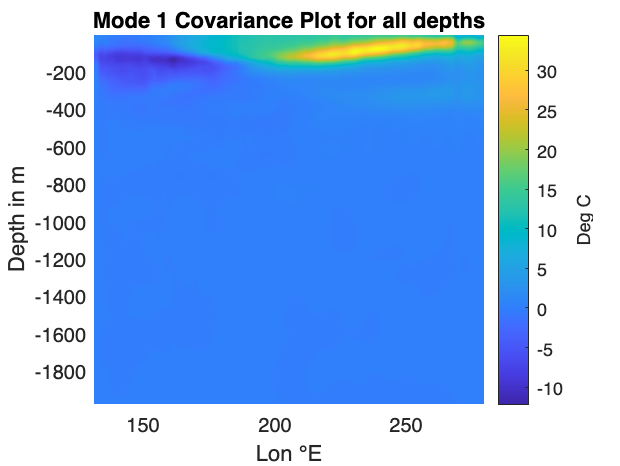

[e,lambda] = eig(C);        %e = eigenvectors, lambda = eigenvalues
lambda = diag(lambda);
if(lambda(1) < lambda(end))
    lambda = fliplr(lambda(:)');
    e = fliplr(e);
end
a = D*e; 

m1 = NaN(149,58);
m1 = reshape(a(:,1),149,58);
pcolor(lon(112:260),-pressure,m1')
shading interp
cb = colorbar;
ylabel(cb,'Deg C')
xlabel('Lon °E')
ylabel('Depth in m')
title('Mode 1 Covariance Plot for all depths')

The above temperature gradient shows that Mode 1 represents El-Nino.

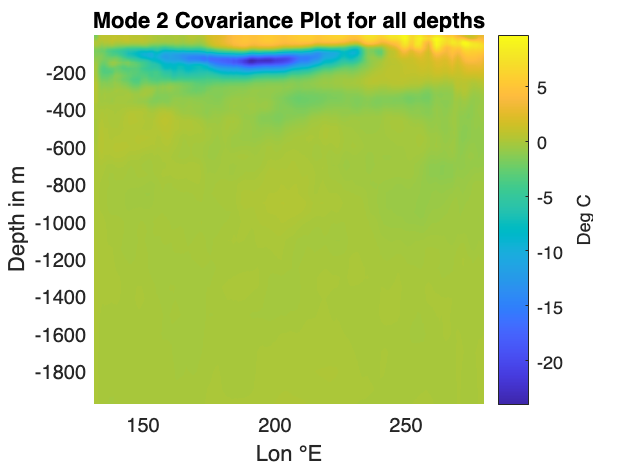

m2 = NaN(149,58);
m2 = reshape(a(:,2),149,58);
pcolor(lon(112:260),-pressure,m2')
shading interp
cb = colorbar;
ylabel(cb,'Deg C')
xlabel('Lon °E')
ylabel('Depth in m')
title('Mode 2 Covariance Plot for all depths')

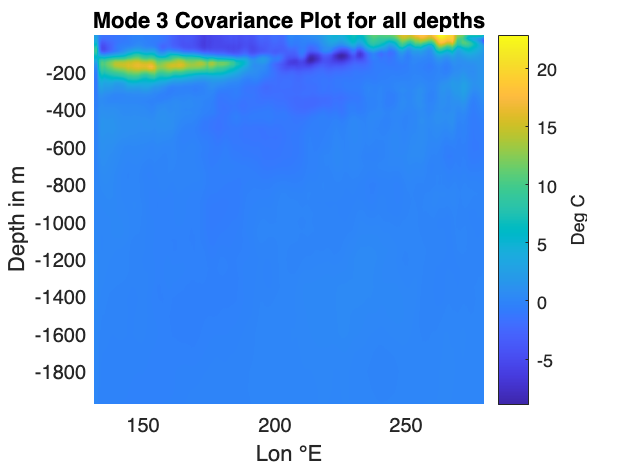

m3 = NaN(149,58);
m3 = reshape(a(:,3),149,58);
pcolor(lon(112:260),-pressure,m3')
shading interp
cb = colorbar;
ylabel(cb,'Deg C')
xlabel('Lon °E')
ylabel('Depth in m')
title('Mode 3 Covariance Plot for all depths')

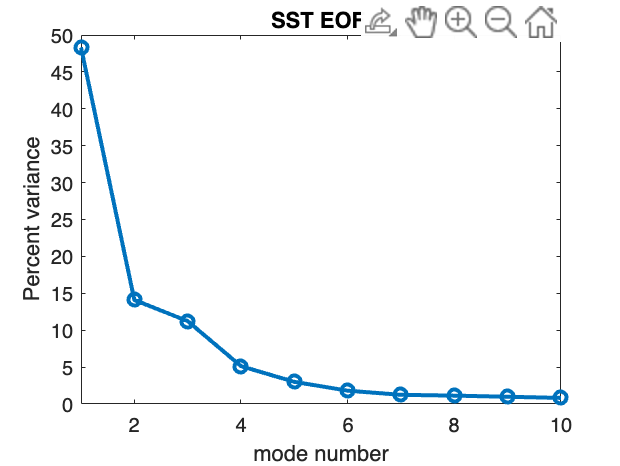

figure (2)
pvar = lambda/sum(lambda)*100;
plot(pvar,'o-','LineWidth',2)
xlim([1,10])
ylabel('Percent variance')
xlabel('mode number')
title('SST EOF ')

Mode 1, explains 48.5% of variabilty

Followed by Mode 2 which is at 14.7% and Mode 3 at 12%

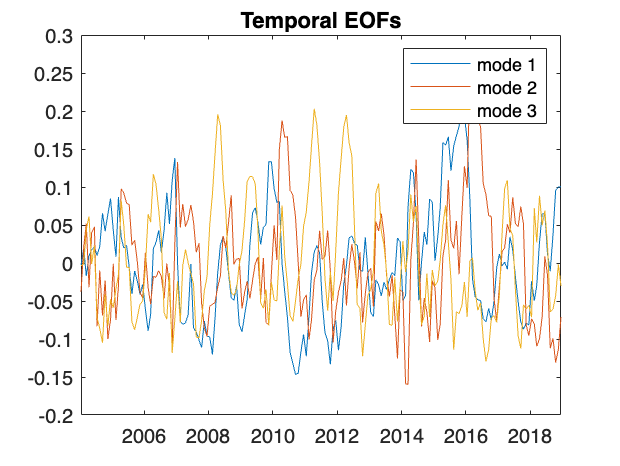

t_data =datetime(tmon,'ConvertFrom', 'datenum', 'Format', 'dd-MM-yy');
figure (3)
plot(t_data,e(:,1:3))
legend('mode 1','mode 2','mode 3')
title('Temporal EOFs')

Mode 3 is seasonal cycle

Mode 1 is El-Nino

load oni_index.mat

Import ONI data and crop data of (2004-2018) and find relevant index values (649 to 828) 

%t = datetime(2004,1,15) + calmonths(0:179);
%Convert t to datetime format
%The required ONI data's index is from 649 to 828
tmon;
t_data =datetime(tmon,'ConvertFrom', 'datenum', 'Format', 'dd-MM-yy');
t_nino = datetime(oni_datenum,'ConvertFrom', 'datenum', 'Format', 'dd-MM-yy');
t_nino(649)

ans = datetime
   15-01-04


t_nino(828)

ans = datetime
   15-12-18


Scale the eigen vectors to 0.085 times and overplot on Nino index variation

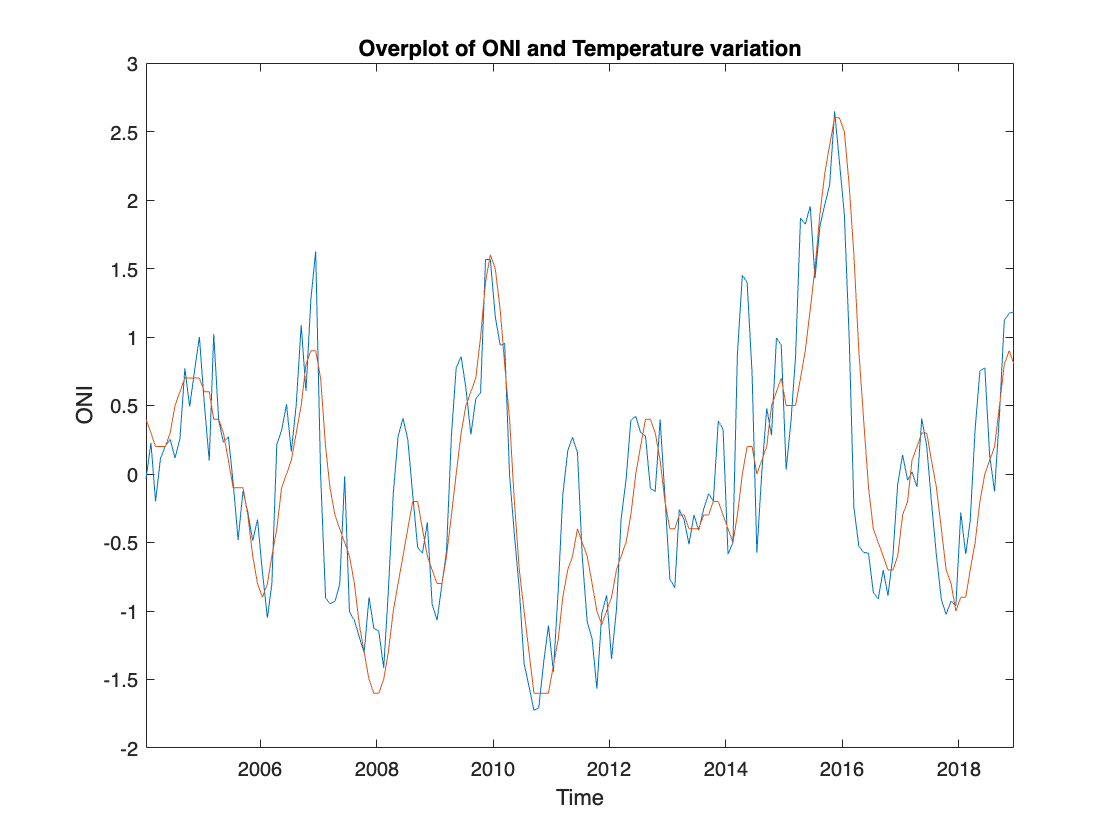

figure(4)
clf
%Scaling the temperature values by 0.085
plot(t_data,e(:,1)/0.085)
hold on
plot(t_nino(649:828),oni_index(649:828))
hold off
title('Overplot of ONI and Temperature variation')
xlabel('Time')
ylabel('ONI')

The correlation of Temperature Mode 1 with ONI

corr(oni_index(649:828),e(:,1))

ans = 0.8394

### **Results :**

The first 3 SST Modes explains about 74% of its variation

The first 3 Salinity Modes explains about 64% of its variation

Correlation of ONI and with Mode 1 of Temperature profile is ~0.84

Correlation of ONI and with Mode 1 of Salinity profile is ~0.78

### **Conclusions: **

3 Modes of Temperature determines majority of its variation

Analyzing Temporal plots suggests that Mode 1 is El-Nino and Mode 3 is Seasonal Cycle.

El-Nino is major influencer of Temperature and salinity variation in tropical pacific ocean.

Mode 1’s plot explains how the temperature anomaly gradient during El-Nino look like in Pacific ocean.

Mode 1 captures the fact that the rainfall due to El-Nino caused a decrease in salinity in Western Pacific 

Deep water argo data does not give significant El-Nino signal

Salinity has greater impact of seasonal cycles